# СКРИПТЫ И ФУНКЦИИ

## Семинар 6 Скрипты и функции

### Скрипты

Скрипт - эвивалент **copy-paste** кода, который сохранен в отдельный файл, то есть ему присвоено имя 

Этот кусок кода выполняется в том **workspace, **в котором скрипт был вызван

% формируем текст скрипта
script1_text = ["A=12;";...
                "B=C+A;"] % пока не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"

script1_text = 2×1 string array
    "A=12;"
    "B=C+A;"


if ~isfolder(fullfile(get_folder(),"scripts"))
    mkdir(fullfile(get_folder(),"scripts"))
end
rmpath(fullfile(get_folder(),"scripts")); % что происходит на данной строчке объясняется потом

cd(get_folder())
script_file_name = fullfile(".","scripts","script1.m") % имя файла, в который сохраняется скрипт 

script_file_name = ".\scripts\script1.m"

% пишем текст скрипта в файл
writelines(script1_text,script_file_name); % writelines - пишет массив строк в текстовый файл, предполагая, что каждый элемент - это отдельная строка

Работа скрипта при его запуске из рабочей папки, где лежит скрипт

cd(fullfile(get_folder(),"scripts")) % сделаем текущей папкой - папку, где лежит скрипт 
current_folder = pwd();
current_folder

current_folder = 'E:\projects\matlab-seminar\basics\sem5_6\scripts'

clearvars % чистим base воркспейс
some_variable = [];
who


Your variables are:

some_variable  



script1 

Unrecognized function or variable 'C'.

Error in script1 (line 2)
B=C+A;

Почему возникает ошибка?

clearvars
who
C=15 % создаем переменную C

C = 15

A = "Ваше мнение очень важно для нас!"

A = "Ваше мнение очень важно для нас!"

whos

  Name      Size            Bytes  Class     Attributes

  A         1x1               230  string              
  C         1x1                 8  double              



script1
whos

  Name      Size            Bytes  Class     Attributes

  A         1x1                 8  double              
  B         1x1                 8  double              
  C         1x1                 8  double              



A 

A = 12

Очень неприятный побочный эффект! Скрипт подменил переменную А

Что быстрее скрипт или eval?

clear all % чистит все, в том числе скомпилированные файлы
cd(fullfile(get_folder(),"scripts")) 
script_to_test_text = "A=rand(100);B=eig(A);" 

script_to_test_text = "A=rand(100);B=eig(A);"

% пишем текст скрипта в файл
writelines(script_to_test_text,"script_test.m"); 
disp(" script_test : "); tic 

 script_test : 


for ii=1:10    script_test; end
script_mean_time_per_run = toc/10

script_mean_time_per_run = 0.0037

disp(" Eval(script_text) : "); tic

 Eval(script_text) : 


for ii=1:50 eval(script_to_test_text); end
eval_mean_time_per_run = toc/10

eval_mean_time_per_run = 0.0130

clearvars
% вернемся в корневую папку ливскрипта 
cd(get_folder()) % теперь рабочая папке  - это папка, в которй лежит сам ливскрипт
current_folder = pwd();
current_folder

current_folder = 'E:\projects\matlab-seminar\basics\sem5_6'

% выполним этот скрипт
script1

script1 is not found in the current folder or on the MATLAB path, but exists in:
    E:\projects\matlab-seminar\basics\sem5_6\scripts

Change the MATLAB current folder or add its folder to the MATLAB path.

% ошибка! 
% Почему?

### MATLAB path 

Вызов скрипта по имени производится точно также как запрос содержимого переменной с тем же именем.

Когда мы вызываем скрипт по его имени, матлаб:

-  Ищет переменную с таким именем в текущем workspace

- Затем ищет файл с этим именем вначале в текущей папке (**pwd**(), чтобы ее посмотреть) 

- Далее он перебирает папки в MATLAB path, причем в той последовательности, в которой они там написаны (сверху-вниз)

% посмотреть текущий путь
path
folders1 = path()

Пути в **MATLAB path** хранятся в заданной последовательности 

Чтобы в этом убедится создадим два скрипта с одним именем, но разным содержимым:

% создаем два скрипта с одним именем 
script1_folder = fullfile(get_folder(),"scripts1");rmpath(script1_folder); % варнинг можно игнорировать

script2_folder = fullfile(get_folder(),"scripts2");rmpath(script2_folder); % 

% создаем два скрипта с одним именем, но в разных папках (код функции
% make_script можно посмотреть в конце данного скрипта)
make_script(script2_folder,"same_script","disp('Выполняется script из папки scripts2')")  
make_script(script1_folder,"same_script","disp('Выполняется script из папки scripts1')")
% оба скрипта имеют имя script

Добавим путь к первому скрипту в конец **MATLAB path**

folders = path()

folders = 'E:\projects\matlab-seminar\applications\UnconstrainedOptimization\sem15_17;C:\Users\user\Documents\MATLAB;E:\projects\Matlab Files\microwave\functions;E:\projects\Matlab Files\microwave\classes;E:\projects\Matlab Files\microwave\classes\abstracts;E:\projects\Matlab Files\microwave\classes\cst_connection;E:\projects\Matlab Files\microwave\classes\gratings;E:\projects\Matlab Files\microwave\classes\gratings\classes;E:\projects\Matlab Files\microwave\classes\gratings\classes\various functions;E:\projects\Matlab Files\microwave\classes\gratings\functions;E:\projects\Matlab Files\microwave\classes\mathclasses;E:\projects\Matlab Files\microwave\classes\optimization;E:\projects\Matlab Files\microwave\classes\optimization\gops;E:\projects\Matlab Files\microwave\classes\tesing classes;E:\projects\Matlab Files\microwave\classes\typical functions;E:\projects\Matlab Files\microwave\classes\typical functions\functions;E:\projects\Matlab Files\microwave\utils;E:\projects\Matlab Files\micr

folders= path(folders,char(script1_folder)); % доабавляет путь в конец 
same_script

Выполняется script из папки scripts1


Добавим путь ко первому скрипту в конец **MATLAB path**

folders = path(char(script2_folder),folders); % доабавляет путь в начало 
same_script

Выполняется script из папки scripts2


rmpath(char(script2_folder)) % удаляем путь ко второй папке со скриптом 
same_script % теперь опять запускается первый скрипт

Выполняется script из папки scripts1


% savepath()  сохраняет текущий набор путей в файл дефолтного набора путей,
% который загружаются при старте матлаба (не будем ее забивать)
savepath("cur_path.m") % сохраняет в отдельный файл

Графическая оболочка для редактирования путей

pathtool

### Функции

До этого момента мы работали в базовом  **workspace, **то есть том, который загружается при старте матлаб. Заполнение пространства имен происходило путем выполнения операции присвоения при помощи символа "=" как конструкция вида: "variable_name=variable_value". После заполнения **workspace **переменными мы могли оперировать значениями, которые привязаны к их именам, путем ввода инструкций либо в командной строке, либо при помощи скриптов. Инструкции записывались как комбинации символов. При этом символы, соответсвующие именам переменных, содержащимся в **workspace,  **автоматически (при парсинге символов, записывающих эти инструкции) интерпретировались как привязанное к ним содержимое. На примере скрипта подменяющего набор символов для встроенной функции **sin, **мы убедились, что присвоение того же имени новому значению переобозначает данный набор символов, затеняя в данном случае встроенную функцию.

Написание достаточно сложной программы требует создания большого числа переменных, поэтому, оставаясь в рамках одного и того же **workspace, **есть большая вероятность совершить "подмену" переменных (как это происходило в примере со сриптами и функцией **eval**), что приведет к неправильной работе программы. 

Выходом тут является использование синтаксических конструкий, которые позволяют изолировать  пространства имен переменных для различных составных частей программы друг от друга (само содержимое переменных, может при этом быть и не изолировано, но этот вопрос мы будем рассматривать в последующих семинарах для объектов особого типа **handle**). 

Основным  инструментом языка матлаб (и парадигмы функционального программирования), который позволяет создавать изолированное пространство имен являются функции. 

Таким образом, каждая функция имеет свой **workspace, **содержимое которого в момент начала выполнения кода функции определяется именами ее входных аргументов и привязанными к ним значениями ( но не всегда только ими, см. вложенные функции далее). Базовый синтаксис записи кода функций показан ниже:

Функции, как и скрипты могут быть записаны в текстовые файлы с расщирением "**.m**"

Когда происходит вызов функции, то есть, матлаб встречает языковую конструкцию вида "**function_name(...)**" для него это значит, что надо найти ее имя и код функции либо в **workspace**, либо в **matlab path**  и запустить его (об этом ему говорят круглые скобки). В круглых скобках после имени функции указываются имена аргументов (или непосредственно значения) соответсвующие переменным того **workspace, **из которого происходит вызов функции (**caller workspace**).

Воркспейс функции формируется в момент ее вызова. То есть, когда мы вызываем функцию, передавая в качестве аргументов имена переменных,  в  **workspace** функци добавляются переменные, имеющие значения,  соответсвующие именам переменных из **caller workspace, ** а имена, заданным в заголовке функции. В качестве аргументов могут выступать непосредственно значения (числа **double**, символы **string**/**char**, более сложные типы данных, такие как **struct**, **cell **и др.)

functions_folder = fullfile(get_folder(),"functions_folder")

functions_folder = "E:\projects\matlab-seminar\basics\sem5_6\functions_folder"

if isfolder(functions_folder)
    rmpath(functions_folder) % удаляем из пути матлаб папку с функциями (физически она не удаляется)
end
make_function(functions_folder,... % folder 
                        "swap",... % function name 
                        ["A" "B"],...% input arguments
                        ["A" "B"],...% output arguments
                        "%Эта функция меняет местами переменные и отображает свой workspace",...
                        "C=A;A=B;B=C;",...
                        "disp('Содержимое workspace функции swap:')",...
                        "who % функция who ( и прочие функции работы с workspace) теперь будут работать в workspace это фукнции)")% function body
% буду иногда пользоваться самодельной функцией make_function, она генерирует код
% функции и текста (создает тектовый файл и пишет туда строки)
% функция read_code - по имени фукнции ищет файл с ней и считывает код
% функции

Сгенерированный make_function файл этой функции будет выглядить вот так (в этом можно убедиться открыв созданный файл в редакторе):

Вызов функции производится при помощи записи "function_name()", где function_name - имя вызываемой функции.

[A,B] = swap("A","B") % вызываем функцию при помощи оператора "()"

Unrecognized function or variable 'swap'.

addpath(functions_folder);% добавляем папку в MATLAB path

read_code("swap") % самодельная функция, которая выводит код по имени функции

ans =     "function [A,B] = swap(A,B)
     %Эта функция меняет местами переменные и отображает свой workspace
     C=A;A=B;B=C;
     disp('Содержимое workspace функции swap:')
     who % функция who ( и прочие функции работы с workspace) теперь будут работать в workspace это фукнции)
     end
     "


read_code("sin") % код встроенный функций как правило недоступен

ans = "sin"

clearvars -except functions_folder
[A,B] = swap("A","B") % работает

Содержимое workspace функции swap:

Your variables are:

A  B  C  



A = "B"

B = "A"

disp('Содержимое workspace base:')

Содержимое workspace base:


who


Your variables are:

A                 B                 functions_folder  



help swap % выдает докстринг в консоль

 Эта функция меняет местами переменные и отображает свой workspace



doc swap % отображает его в браузере 


Можно игнорировать выходные аргументы (второй аргумент, возвращаемый функцией не присваивается к новой переменной)

clearvars -except functions_folder
[~,B] = swap("A","B") % выходные аргументы функции можно игнорировать

Содержимое workspace функции swap:

Your variables are:

A  B  C  



B = "A"

A = swap("A","B");

Содержимое workspace функции swap:

Your variables are:

A  B  C  



who


Your variables are:

A                 B                 functions_folder  



Функция может игнорировать входные аргументы 

ignore_arguments(9)

ans = 0.4121

ignore_arguments(9,10)

ans = 0.4121

ignore_arguments(9,10,12)

ans = 0.4121

Зачем это нужно? 

Позволяет сохранить сигнатуру функции как трех-аргументной

% данная функция не имеет входных и выходных аргументов
make_function(functions_folder,... % folder 
                        "noargs",... % function name 
                        "",...% input arguments
                        "",...% output arguments
                        "disp('Содержимое workspace функции noargs:')",...
                        "who")

noargs()

Содержимое workspace функции noargs:


read_code("noargs")

ans =     "function [] = noargs()
     disp('Содержимое workspace функции noargs:')
     who
     end
     "


#### **Указатель на простую функцию**

 Иногда нужно передать функцию в качестве аргумента, для этого можно перед ее именем поставить знак "@" и она превратится в указатель на функцию

simple_fun_handle = @swap % указатель на функцию

simple_fun_handle = function_handle with value:
    @swap


class(simple_fun_handle) % относится к особому классу объектов

ans = 'function_handle'

[A,B] = simple_fun_handle(1,2)

Содержимое workspace функции swap:

Your variables are:

A  B  C  



A = 2

B = 1

Указатели на функцию относятся к классу **function_handle**

class(simple_fun_handle) % особый тип объектов function_handle

ans = 'function_handle'

Например код функции, которая вызывает другую функцию может выглядить так:

[A,B] = call_handle("A","B",simple_fun_handle)

Содержимое workspace функции swap:

Your variables are:

A  B  C  



A = "B"

B = "A"

% можно преобразовывать строки в указатели на функции
fun_handle = str2func("sin")

fun_handle = function_handle with value:
    @sin


Массив указателей на функцию можно хранить в массиве ячеек:

% arrayfun - применяет указатель на функцию на каждом элементе массива,
% результат, который она возвращает пытается сложить в массив если вызвана
% с признаком ...,'UniformOutput',true), если ...,'UniformOutput',false) -
% то кажыдй результат вызова вкладывается в свою ячейку, таким образом, на
% выходе имеем массив ячеек размером со входной массив 
fun_handles_cell = arrayfun(@str2func,["sin" "cos" "svds"],'UniformOutput',false) % здесь приходится делать массив ячеек,

fun_handles_cell = 1×3 cell array
    {@sin}    {@cos}    {@svds}


% так как указатели на функции нельзя складывать в один массив (не знаю
% почему)


Пример. вызов большого количества функций  в цикле

A = rand(5);
for f = fun_handles_cell
    disp("Функция с именем " + string(func2str(f{1})) + " дает :") % func2str - обратное к str2func действие 
    f{1}(A)
end

Функция с именем sin дает :


ans =     0.8263    0.8295    0.7224    0.1265    0.2814
    0.7674    0.7501    0.6098    0.7410    0.8210
    0.1703    0.7005    0.4923    0.8382    0.5563
    0.5869    0.5915    0.7238    0.7625    0.6048
    0.7273    0.1076    0.7370    0.5766    0.3082


Функция с именем cos дает :


ans =     0.5633    0.5586    0.6915    0.9920    0.9596
    0.6412    0.6614    0.7926    0.6716    0.5709
    0.9854    0.7137    0.8704    0.5454    0.8310
    0.8096    0.8063    0.6900    0.6470    0.7964
    0.6863    0.9942    0.6759    0.8170    0.9513


Функция с именем svds дает :


ans =     3.3780
    0.9380
    0.6740
    0.3672
    0.0554


fun_handles_struct = arrayfun(@(X) struct("fun",str2func(X)),["sin" "cos" "svds"]) 

#### Метаданные из указателя на функцию

simple_fun_handle = @swap

simple_fun_handle = function_handle with value:
    @swap


functions(simple_fun_handle) % вытягивает метаинформацию из указателя на функцию

ans = struct with fields:
    function: 'swap'
        type: 'simple'
        file: 'E:\projects\matlab-seminar\basics\sem5_6\functions_folder\swap.m'


%  - name имя функции оригинала
%  - type тип функции simple/anonymous/nested 
%  - file
function_file_name = functions(@swap).file

function_file_name = 'E:\projects\matlab-seminar\basics\sem5_6\functions_folder\swap.m'

#### **Анонимные функции - функции, не имеющие своего собственного файла - anonymous**

Тоже относятся к классу **function_handle**

 Нет файла, зато есть **workspace**, который формируется в момент создания функции из того **workspace**

В приведенном выше коде: 

- anonymous_function_handle - имя создаваемой функции

 -  ARG1,ARG2,ARG3 - символы, обозначенные как входные аргументы, 

-  (ARG1,ARG2,ARG3, WS_VAR1,WS_VAR2) - тело функции - код, в котором фигурируют  имена входных аргументов, а также имена переменных, имеющихся в текущем **workspace**

При интепретации кода анонимной функции для нее создается свой **workspace, **в который входят (с теми же именами) переменные WS_VAR1,WS_VAR2, то есть  переменные **workspace, **в котором происходится создание анонимной функции,  которые используются в ее коде. В момент создания анонимной функции создается "срез" того **workspace, **в котором она создаеся .

%пример 
anon_fun = @(f,x) ((f(x+10*eps)-f(x))/(10*eps))

anon_fun = function_handle with value:
    @(f,x)((f(x+10*eps)-f(x))/(10*eps))


sin_fun = @sin;
x = transpose(linspace(-pi,pi,100));

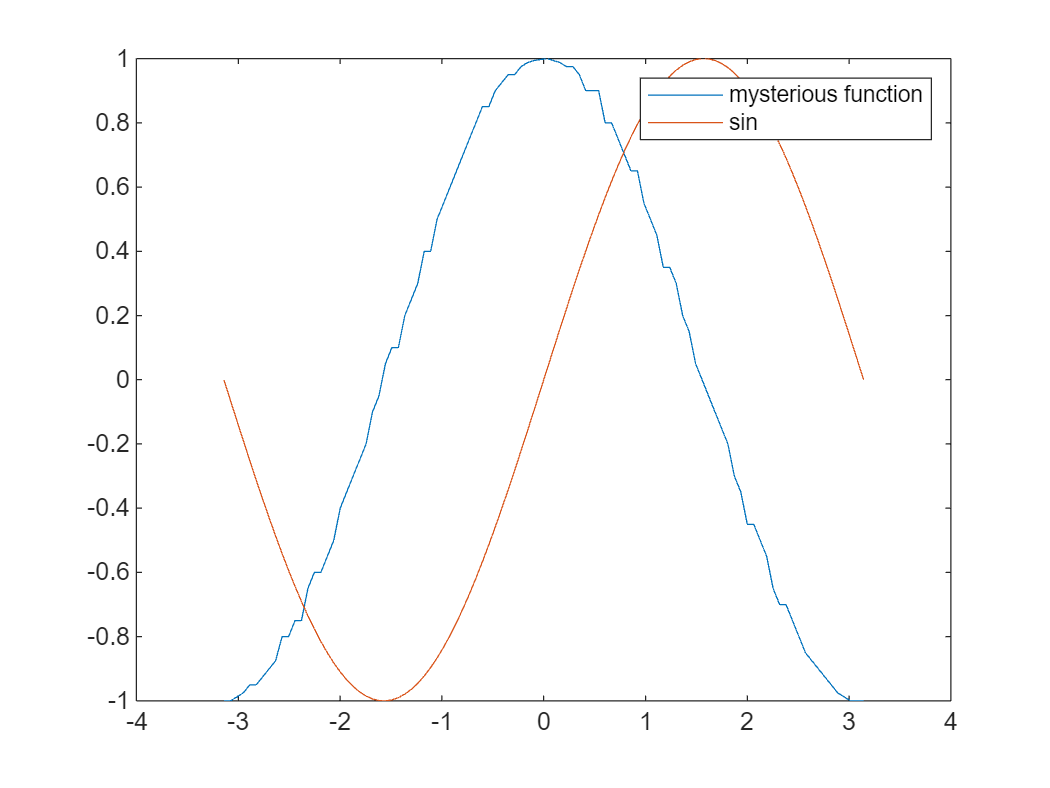

plot(x,anon_fun(sin_fun,x),x,sin_fun(x));
legend("mysterious function","sin")

clearvars -except anon_fun
f = @sin;% в текущем workspace "приписали" значение к символу "f"
anon_fun2 = @(x) ((f(x+10*eps)-f(x))/(10*eps));% создаем анонимную функцию, 
% в коде которой фигурирует переменная "f", но, в отличие от anon_fun, символ "f" 
% не обозначени как аргумент (так как его нет 

f=@cos; % в текущем workspace заменили значение, приписанное к символу "f"
anon_fun3 = @(x) ((f(x+10*eps)-f(x))/(10*eps)); % код этой функции точно такой же

Теперь у функций **anon_fun2** и **anon_fun3 **код одинаковый, а содержимое воркспейсов разное, так как  в них запечатлены разные "срезы" одного и того же воркспейса, но в разные моменты времени

x = transpose(linspace(-pi,pi,100));
anon_fun2(x) - anon_fun(@sin,x)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anon_fun3(x) - anon_fun(@cos,x)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


class(anon_fun)
functions(anon_fun)

При создании анонимная функция копирует из **workspace**, в котором она создается, в свой  **workspace** те переменные, которые есть в ее коде.

В данном случае это переменная f - указатель на функцию


disp("anon_fun workspace:")
functions(anon_fun).workspace{1} % содержимое воркспейса анонимной функции
disp("anon_fun2 workspace:")
functions(anon_fun2).workspace{1} % содержимое воркспейса анонимной функции

Меняем код анонимной функции и создаем новую анонимную функцию из старой

anon_fun_code = functions(anon_fun).function; % код функции в виде строки
new_anon_fun_code = replace(anon_fun_code,"eps","1e-6");% replace- функция для работы 
% со строками - позволяет заменить последоватлеьность символов - другой, в
% данном случае заеняет "eps" в коде анонимной функции на "1e-6"
new_anon_fun = str2func(new_anon_fun_code)

new_anon_fun = function_handle with value:
    @(f,x)((f(x+10*1e-6)-f(x))/(10*1e-6))


new_anon_fun()

Not enough input arguments.

Error in LiveEditorEvaluationHelperE1314287409>@(f,x)((f(x+10*1e-6)-f(x))/(10*1e-6))

Как сделать так, чтобы сохранился workspace копируемой  функции?

Анонимные функции можно коневертировать в символьные 

% анонимые функции можно конвертировать в символьные (иногда получается
% криво)
sym_fun = sym(anon_fun2)

$$sym\_fun = \frac{2251799813685248\,\sin\left(x+\frac{5}{2251799813685248}\right)}{5}-\frac{2251799813685248\,\sin\left(x\right)}{5}$$

sym_fun_integral = sym(@(x)sin(x)) - int(sym_fun)

$$sym\_fun\_integral = \frac{2251799813685248\,\cos\left(x+\frac{5}{2251799813685248}\right)}{5}-\frac{2251799813685248\,\cos\left(x\right)}{5}+\sin\left(x\right)$$

И обратно....

F = matlabFunction(sym_fun_integral,'Vars','x') % теперь это снова анонимая функция 

F = function_handle with value:
    @(x)cos(x+2.220446049250313e-15).*4.503599627370496e+14-cos(x).*4.503599627370496e+14+sin(x)


functions(F)

ans = struct with fields:
            function: '@(x)cos(x+2.220446049250313e-15).*4.503599627370496e+14-cos(x).*4.503599627370496e+14+sin(x)'
                type: 'anonymous'
                file: ''
           workspace: {[1×1 struct]}
    within_file_path: ''


functions(F).workspace{1}

ans = struct with no fields.


F(x)

ans =    -0.0000
    0.0616
   -0.0016
   -0.0018
   -0.0011
   -0.0620
    0.0033
    0.0077
    0.0138
    0.0219


Затеняем анонимной функцией встроенную

N=3;
zu = @(k,x) power(-1,k).*power(x,1+2*k)./(factorial(1+2*k))

zu = function_handle with value:
    @(k,x)power(-1,k).*power(x,1+2*k)./(factorial(1+2*k))


sin = @(x) sum(zu(0:N,x))

sin = function_handle with value:
    @(x)sum(zu(0:N,x))


sin(2) % затеняем встроенную функцию

ans = 0.9079

builtin('sin',2) % функция builtin позволяет вызвать встроенную функцию даже когда она затенена в данном workspace

ans = 0.9093

Теперь можно попробовать увеличить число N и перезапустить ячейку выше

### Полезные штуки для функций 

#### **Произвольное число входных аргументов - *****varargin*** 

#### **Как узнать число входных аргуметов, находясь внутри функции - *****nargin*** 

functions_folder = fullfile(get_folder(),"functions_folder")

functions_folder = "E:\projects\matlab-seminar\basics\sem5_6\functions_folder"

make_function(functions_folder,... % folder 
                        "vararargin_function",... % function name 
                        "A,B,varargin",...% input arguments
                        "out",...% output arguments
                        "out = A+B;",...
                        "disp('nargin =>' + string(nargin));",...
                        "disp('numel(varargin) =>' + string(numel(varargin)));",...
                        "for v=varargin","out = out + v{1};","end")

vararargin_function(10,20)

nargin =>2
numel(varargin) =>0


ans = 30

vararargin_function(10,20,40,78,149)

nargin =>5
numel(varargin) =>3


ans = 297

vararargin_function("a","b","c")

nargin =>3
numel(varargin) =>1


ans = "abc"

#### **Произвольное число вЫходных аргументов  - *****varargin***

#### **Как узнать число выходных аргументов, находясь внутри функции - *****nargout***

#### **Как прерывать выполнение функции - *****return*** 

[A,B] = vararargout_function(rand(100))

Число входных аргументов: 1
Число вЫходных аргументов: 2


A =    50.1725
    5.6490
    5.5533
    5.3200
    5.1967
    5.1215



B =

     []



[A,B] = vararargout_function(rand(100),rand(100))

Число входных аргументов: 2
Число вЫходных аргументов: 2


A =    49.8932
    5.4779
    5.3371
    5.3087
    5.2276
    5.1291


B =    50.4214
    5.4910
    5.4198
    5.2470
    5.2072
    5.0820


[A,~] = vararargout_function(rand(100),rand(100)) % тильда внутри функции считается за аргумент

Число входных аргументов: 2
Число вЫходных аргументов: 2


A =    50.1656
    5.5903
    5.4330
    5.2249
    5.2009
    5.0720


[~,B] = vararargout_function(rand(100),rand(100),rand(100))

Число входных аргументов: 3
Число вЫходных аргументов: 2


B =    50.1093
    5.5101
    5.4228
    5.3576
    5.2184
    5.1283


disp("Один входной аргумент, один выходной: " + string(timeit(@()vararargout_function(rand(500)),1)))

Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Число входных аргументов: 1
Число вЫходных аргументов: 1
Один входной аргумент, один выходной: 0.020869



disp("один входной аргумент, два выходных: " + string(timeit(@()vararargout_function(rand(500)),2)))

Число входных аргументов: 1
Число вЫходных аргументов: 1


Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
Число входных аргументов: 1
Число вЫходных аргументов: 2
один входной аргумент, два выходных: 0.01617



disp("два входных, два выходных: " + string(timeit(@()vararargout_function(rand(500),rand(500)),2)))

Число входных аргументов: 2
Число вЫходных аргументов: 1
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
Число входных аргументов: 2
Число вЫходных аргументов: 2
два входных, два выходных: 0.030333



disp("три входных, два выходных: " + string(timeit(@()vararargout_function(rand(500),rand(500),rand(500)),2)))

Число входных аргументов: 3
Число вЫходных аргументов: 1
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
Число входных аргументов: 3
Число вЫходных аргументов: 2
три входных, два выходных: 0.038619


Так как воркспейс функции - это точно такой же воркспейс как и базовый, внутри функций можно применять методы для работы с воркспейсом, которые обсуждали ранее

Для примера можно использовать функцию exist (хотя есть более прозрачные способы гарантировать существование переменных)

help exist

 exist  Check existence of variable, script, function, folder, or class
    exist(NAME) returns:
      0 if NAME does not exist
      1 if NAME is a variable in the workspace
      2 if NAME is a file with extension .m, .mlx, .mlapp, or .sfx, or NAME
        is the name of a file with a non-registered file extension 
        (.mat, .fig, .txt).
      3 if NAME is a MEX-file on the MATLAB search path
      4 if NAME is a Simulink model or library file on the MATLAB search path
      5 if NAME is a built-in MATLAB function. This does not include classes
      6 if NAME is a P-code file on the MATLAB search path
      7 if NAME is a folder
      8 if NAME is a class (exist returns 0 for Java classes if you
        start MATLAB with the -nojvm option.)
 
    exist(NAME,'builtin') checks only for built-in functions.
    exist(NAME,'class') checks only for classes.
    exist(NAME,'dir') chec

exist_check_fun(9)

ans = 9

exist_check_fun(9,15)

ans = 24

exist_check_fun(9,15,16)

ans = 40

Поменяем содержимое файла функции **swap**

уберем из функции swap disp и who

% уберем из функции swap disp и who
functions_folder = fullfile(get_folder(),"functions_folder");
make_function(functions_folder,... % folder 
                        "swap",... % function name 
                        ["A" "B"],...% input arguments
                        ["A" "B"],...% output arguments
                        "C=A;A=B;B=C;")% function body
addpath(functions_folder)

[A,B] = swap("A","B")

A = "B"

B = "A"

#### Вложенные (nested) функции

Вложенные функции - это функции декларированные в теле функции. 

Для них доступен воркспейс внешней функции, аргументы вложенной функции могут "затенять"  аргументы внешней функции

[A,B,nested_fun_handle] = external_fun("A","B") % работает! 


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  



A = "B"

B = "A"

nested_fun_handle = function_handle with value:
    @external_fun/nested_fun


Третий вид function_handle : nested

functions(nested_fun_handle)

ans = struct with fields:
     function: 'external_fun/nested_fun'
         type: 'nested'
         file: 'C:\Users\user\AppData\Local\Temp\Editor_jjvhy\LiveEditorEvaluationHelperE401506332.m'
    workspace: {[1×1 struct]}


% похоже на анонимную функцию, так как в ее воркспейспе сохраняется
% воркпейс внешней функции, окружение, в котором она должна работать

Мультивложенная функция

[A,B] = multi_embedded_fun("A","B") % работает! 


Your variables are:

A  B  



A = "B"

B = "A"

- Поставим breakpoint  в редакторе кода функции swap 

- Вызвать в командной строке матлаба функцию dbstack() -

- Подивиться на стэк!

timeit(@()swap("A","B"))

ans = 0

timeit(@()external_fun("A","B"))


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

workspace вложенной функции

Your variables are:

A  B  


Your variables are:

A  B  

wo

ans = 6.1431e-04

timeit(@()multi_embedded_fun("A","B"))


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  


Your variables are:

A  B  



ans = 4.9451e-04

В одном файле может быть несколько не вложенных функций

B = two_fun_one_file("A")

B = 'string'

B = 'string'

B = 'string'

#### Перемещение по стэку!

Выполнить функцию eval()  в чужом воркспейсе  -  evalin(workspace, expression) % workspace  может быть либо 'base' - базовый workspace, либо 

help evalin

 evalin Evaluate expression in workspace.
    evalin(WS,'expression') evaluates 'expression' in the context of
    the workspace WS.  WS can be 'caller' or 'base'.  It is similar to EVAL
    except that you can control which workspace the expression is
    evaluated in.
 
    [X,Y,Z,...] = evalin(WS,'expression') returns output arguments from
    the expression.
 
    Security Considerations: When calling evalin with untrusted user input,
    validate the input to avoid unexpected code execution.
  
    See also eval, assignin.

    Documentation for evalin
    Other uses of evalin



`Как сломать функцию`

`Вторая функция имеет вид:`

C = input_expression("rand(10)")

  Name             Size            Bytes  Class     Attributes

  C               10x10              800  double              
  expression       1x1               182  string              



Output argument "C" (and possibly others) not assigned a value in the execution with "sem6>input_expression" function.

Присвоить перемнной заданного workspace значение, рассчитанное в данном воркспейс assignin(workspace,variable_name,value)

clearvars
assignin("base","newVar",whos)
newVar


newVar = 

  0×1 empty struct array with fields:

    name
    size
    bytes
    class
    global
    sparse
    complex
    nesting
    persistent



Воркспейс функции после ее выполнения чистится, соответственно все переменные, которые не были возвращены вызывающей функции ('caller' вниз по стеку) будут стерты из памяти

on_clean_up_check("disp('Начало работы')", @()disp('Очистка '))

Начало работы
Очистка 


on_clean_up_check("'", @()disp('Очистка ')) % функция onCleanup работает когда в коде ошибка!

Очистка 


Error using sem6>on_clean_up_check (line 564)
Error: Character vector is not terminated properly.

Рекомендуется всегда при работе при помощи функций с портами и низкоуровневыми функциями для записи в файл использовать 

#### Хранение данных в памяти функции - **persistent**

По умолчанию, после выполнения кода функции, ее воркспейс чистится из памяти, но можно сделать так , чтобы чистился не полностью, это позволяет при последующих запусках функции уже иметь в ее **workspace**  переменные, созданные при ее предыдущих вызовах, для этого в коде функции надо обозначить переменные аннотацией persistent.

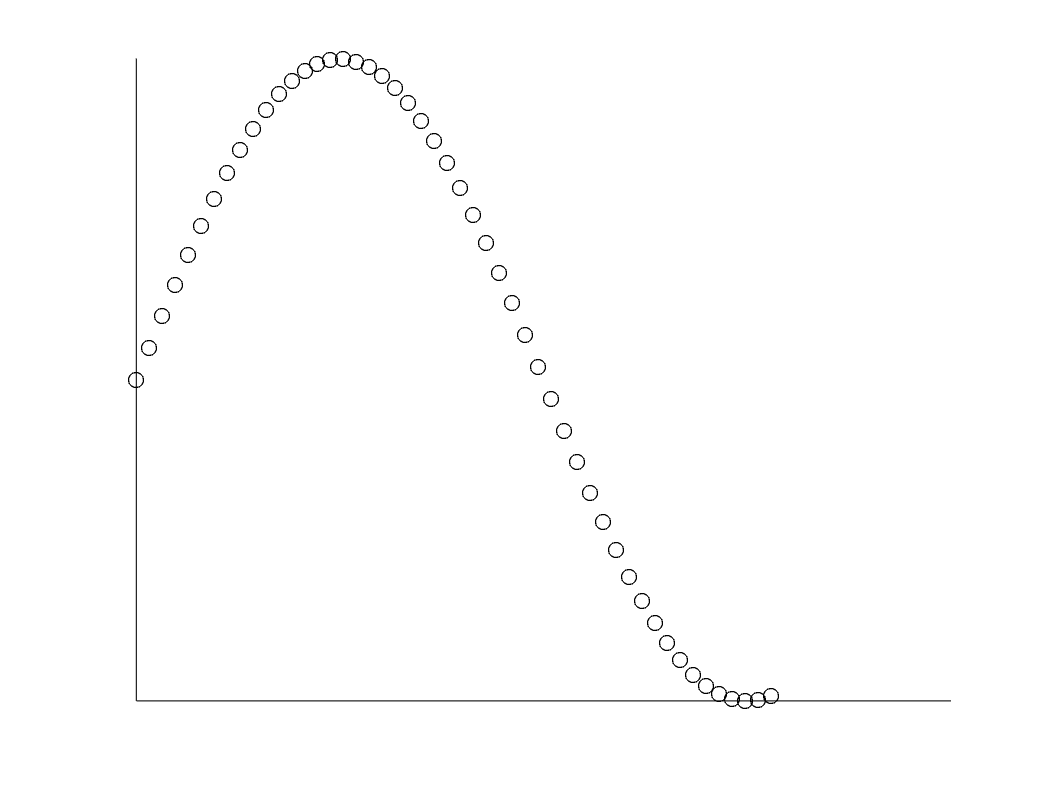

dx = 0.1;
f = @sin;
for a=1:50
    persistent_func(f,dx); % в качестве аргументов в функцию передается только функция и величина шага, значение координаты (x в коде функции) остается с предыдущего вызова 
    pause(0.2) % ждем пол секунды
end

clear persistent_func % содержимое persistent переменных чистится при помощи функции clear имя_функции или clear('имя функции')

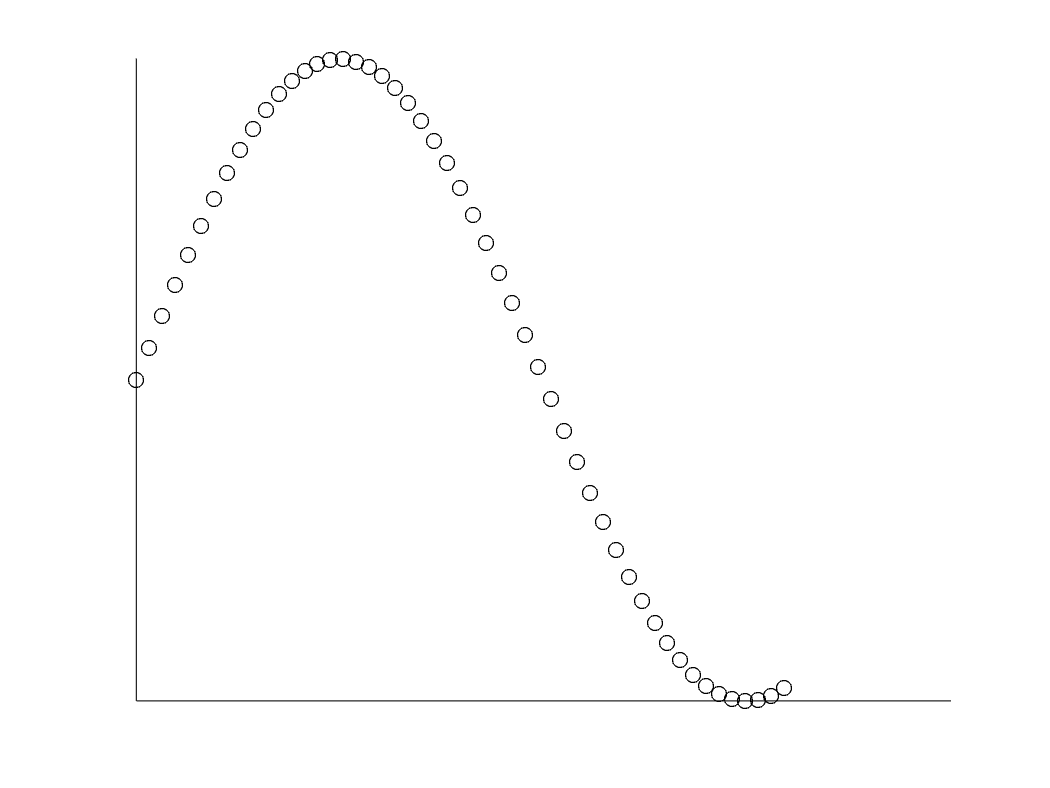

ans = -0.9589

persistent_func(f,dx) % опять стартуем с нулевой координаты 

### Аннотация типов входных аргументов - блок arguments...end

Несмотря на то, что матлаб не требует объявления типов переменных (динамическая типизация) при написании функций, особенно тех, которые являются интерфейсом взаимодействия с "внешним миром", возникает необходимость создания большого числа проверок аргументов функций, чтобы избежать непредсказуемого поведения. Проверять приходится типы, размерность, принадлежность к определенному диапазону или набору значений и т.п.

В современном матлаб это можно делать при помощи блока **arguments...end**

Общие правила 

`arguments`

    `argName1 (dimensions) class {validators} = defaultValue`

`    ...`

    `argNameN ...`

`end`

out = annotated_arguments(1.3,rand([10,2]),"ghj")

Error using sem6>annotated_arguments (line 479)
Invalid argument at position 1. Value must be integer.

out = annotated_arguments(3,rand([10,2]),"ghj")

Error using sem6>annotated_arguments (line 480)
Invalid argument at position 2. Value must be a vector.

out = annotated_arguments(3,rand([10,1]),"ghj")

Error using sem6>annotated_arguments (line 481)
Invalid argument at position 3. Value must be a member of this set:
    'sin'
    'cos'
    'tan'

out = annotated_arguments(3,rand([10,1]),"sin")

out =     0.9934    0.8379    0.7432
    0.3051    0.3004    0.2959
    0.5517    0.5242    0.5005
    0.0726    0.0725    0.0724
    0.0948    0.0947    0.0945
    0.7004    0.6445    0.6008
    0.3392    0.3327    0.3266
    0.7888    0.7095    0.6515
    0.2270    0.2250    0.2231
    0.6087    0.5718    0.5412


out = annotated_arguments(3,linspace(-pi,pi,100),"cos")

out =    -3.1416   -1.0000    0.5403
   -3.0781   -0.9980    0.5420
   -3.0147   -0.9920    0.5471
   -2.9512   -0.9819    0.5554
   -2.8877   -0.9679    0.5670
   -2.8243   -0.9501    0.5816
   -2.7608   -0.9284    0.5991
   -2.6973   -0.9029    0.6193
   -2.6339   -0.8738    0.6419
   -2.5704   -0.8413    0.6665


livescript_helper= functions(@annotated_arguments).file

livescript_helper = 'C:\Users\user\AppData\Local\Temp\Editor_jjvhy\LiveEditorEvaluationHelperE401506332.m'

#### **Использование блока arguments для создания аргументов типа name-value pair**

cd(get_folder)

name_value_pairs("A",5)

ans =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0633   -0.0633   -0.0633   -0.0633   -0.0633
   -0.1253   -0.1253   -0.1253   -0.1253   -0.1253
   -0.1849   -0.1849   -0.1849   -0.1849   -0.1849
   -0.2411   -0.2411   -0.2411   -0.2411   -0.2411
   -0.2932   -0.2932   -0.2932   -0.2932   -0.2932
   -0.3408   -0.3408   -0.3408   -0.3408   -0.3408
   -0.3837   -0.3837   -0.3837   -0.3837   -0.3837
   -0.4217   -0.4217   -0.4217   -0.4217   -0.4217
   -0.4552   -0.4552   -0.4552   -0.4552   -0.4552


#### **Использование блока arguments для создание произвольного числа аргументов типа name-value pair**

repeating_name_value_pairs("A",35)

ans = "A=35"

repeating_name_value_pairs("A",35,"b",67)

ans = 1×2 string array
    "A=35"    "b=67"


repeating_name_value_pairs("A",35,"b",67,"C",78)

ans = 1×3 string array
    "A=35"    "b=67"    "C=78"


ПЕРЕД ВЫХОДОМ - ЗАПУСТИТЬ ЭТУ ЯЧЕЙКУ, ЧТОБЫ ПОЧИСТИТЬ ВРЕМЕННЫЕ ПАПКИ (УДАЛЯЮТСЯ ВСЕ ПАПКИ, ЛЕЖАЩИЕ В КОРНЕВОМ КАТАЛОГЕ КРОМЕ "**pdfs**")

dir_Struct = dir(get_folder());
is_dir = arrayfun(@(X)X.isdir,dir_Struct);
if any(is_dir)
    dir_Struct = dir_Struct(is_dir);
    folders_to_remove_names = arrayfun(@(X)string(X.name),dir_Struct);
    folders_to_remove_names = folders_to_remove_names(:);
    is_dir = folders_to_remove_names==["." ".." "pdfs"];
    is_dir = ~any(is_dir,2);
    if ~any(is_dir)
        clearvars
        return
    end
    dir_Struct = dir_Struct(is_dir);
    full_dirs = arrayfun(@(X) string(fullfile(X.folder,X.name)),dir_Struct);
    full_dirs = transpose(full_dirs(:));
    for d = full_dirs
        rmpath(d);
        rmdir(d,'s');
    end
end

### BONUS. Пишем простой оптимизатор методами функционального программирования

    Для иллюстрации возможностей функционального программирования, далее опсиывается простой градиентный оптимизатор, с помощью которого можно находить минимум скалярных функций, в том числе решать задачи наименьших квадратов. 

Немного теории. Что такое градиент функции:

$f(\vec{x})$ - скалярная функция векторного аргумента, где $\vec{x} \in R^n$ - вектор переменных оптимизации.

тогда градиент этой функции в пространстве $R^n$ имеет вид :


$$\nabla f(\vec{x})=\matrix {\frac{\partial f}{\partial x_1} \cr \vdots \cr \frac{\partial f}{\partial x_n} }$$


Градиент - это вектор в пространстве $R^n$  -  это вектор, который указывает в сторону наибольшего возрастания функции $f(\vec{x})$ . 

Функция численного расчета для расчета градиента произвольной функции может иметь следующий код (по аналогии с численным расчетом производной выше):

Функция **num_grad** находится в файле **num_grad.m, **в той же папке, что и данный скрипт. Отличие от функции расчета производной, которая вводилась ранее, в том, что для расчета градиента мы варьируем отдельно каждую из координат (частная производная), которые затем складываем в один вектор (градиент скалярной функции).

Градиентный оптимизатор - это итерационный алгоритм, который движется в пространстве $R^n$ от точке к точке, так что на кадом шаге итерации  направление вектора перехода от точки к точки противоположно направлению градиента (то есть, направлению максимального возрастания функции). Поэтому ($i+1$) координата в пространстве  $R^n$ выражается через предыдущую точку и градиент функции в виде:

$\vec{x}_{i+1} = \vec{x}_{i} -\mu \hat{g}(\vec{x}_{i}) ,\ где \  \hat{g}(\vec{x}_{i})= \frac {\nabla f(\vec{x}_i)}{||\nabla f(\vec{x}_i)||}$,

$\mu$- скалярный параметры алгоритма (длина шага), который фиксирован (пока), вектор  $\hat{g}(\vec{x}_{i})$ - это вектор единичной длины вдоль градиента, таким образом, мы  оставляем от градиента только его направление, длину шага определяет параметр $\mu$.

Код простого оптимизатора показан ниже:

   Данный алгоритм очень прост, в цикле мы на каждой итерации рассчитываем градиент, нормируем его, оставляя только направление, и движемся вдоль градиента с простоянным шагом (**mu**). Критерием остановки цикла является либо достижение максимального числа итераций, либо когда изменение значения функции (Fval, Fval_previous), либо модуль шага переменных оптимизации (x,x_previous)   для двух последовательных итераций меньше некоторого заданного значения  (**tol**). 

    Следует отметить, что функция ***num_grad,*** в отличие от*** grad_search ***не имеет блока ***arguments...end***, это связано с тем, что так как она является частью итерационного алгоритма ее вызов производится большое количество раз, поэтому она не имеет функций для валидации аргументов. В данном случае мы следуем общему правилу выполнять проверки "на входе", то есть там, где происходит взаимодействие с "внешним миром". В данном случае входом являются входные аргументы функции  ***grad_search*****. **Так как наш оптимизатор универсальный, хочется, чтобы он работал с любыми входными функциями, мы четко определяем типы входных аргументов, а также присваиваем значения по умолчанию для опциональных аргументов. 

Посмотрим как можно применять данные функции, вначале для одномерного поиска минимума скалярной функции:

addpath(get_folder());
F = @(x)sin(x); % ищем минимум данной функции
gradF = @(X) num_grad(F,X) % численный расчет градиента (функция численного расчета градиента имеет два входных аргумента, в данном случае при создании анонимной функции

gradF = function_handle with value:
    @(X)num_grad(F,X)


% gradF, мы передаем первый аргумент num_grad  - собственно функцию, мы
% передаем как параметр, то есть она хранится в workspace данной анонимной
% функции
[xval,fval,iternumber,outflag]=grad_search(-1,F,gradF,"mu",0.01)

xval = -1.5700

fval = -1.0000

iternumber = 1000

outflag = 1×3 logical array
   1   1   1


xval/pi

ans = -0.4997

Можно поиграться с входными опциональными аргументами grad_search: **mu, N, tol**

Теперь решим задачу векторной оптимизации - будем минимизировать квадратичную невязку между измеренными значениями и рассчитанными:


$$F(\vec{x})= \Sigma_k (y_i - f_i(\vec{x}))^2$$


$f_i(\vec{x})=x_1+x_2t_i$, где $t_i = [0:10]$

$y_i$ - "экспериментальные точки" дискретный набор точек, который мы хотим "зафитить" функцией $f(\vec{x},t)$, данная функция зависит от двух переменных оптимизации и рассчитывается для каждого знаечния независимой координаты $t_i$, скалярная функция $F(\vec{x})$ - скалярная функция  - квадратичная невязка (сумма квадратов расхождений между измеренными значениями и рассчитываемыми).

x_true =[0.93; 0.67]; % вектор истинных значений параметров 
t = linspace(0,10,10)'; % вектор независимых переменных
y = x_true(1) + x_true(2)*t;% истинные значения параметров оптимизации x_true
F = @(x)sum(((x(1) + x(2)*t) - y).^2); % воркпейс функции F содержит и экспериментальные и измеренные точки
gradF = @(X) num_grad(F,X) % численный расчет градиента, воркспейс функции gradF содержит и саму функцию F

gradF = function_handle with value:
    @(X)num_grad(F,X)


% запускаем оптимизатор
[xval,fval,iternumber,outflag]=grad_search([0.0 0.0],F,gradF,"mu",0.001,"N",5000)

xval =     0.9267
    0.6700


fval = 1.2024e-04

iternumber = 1686

outflag = 1×3 logical array
   0   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:0.0033281


Видно, что ошибка определения истинных значений имеет тот же порядок, что и длина шага (**mu**), если мы не уперлись в ограничение на число итераций (**N**).

% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.011;
[xval,~,~,~,search_history]=grad_search([0.3 1],F,gradF,"mu",mu,"N",200)

xval =     0.8929
    0.6809


search_history =     0.3000    0.2987    0.2974    0.2961    0.2948    0.2935    0.2923    0.2911    0.2899    0.2887    0.2876    0.2865    0.2854    0.2844    0.2834    0.2825    0.2818    0.2812    0.2807    0.2806    0.2810    0.2826    0.2876    0.2984    0.3082    0.3190    0.3284    0.3390    0.3481    0.3583    0.3669    0.3768    0.3849    0.3946    0.4022    0.4116    0.4189    0.4281    0.4351    0.4441    0.4507    0.4595    0.4658    0.4744    0.4804    0.4888    0.4946    0.5027    0.5083    0.5162
    1.0000    0.9891    0.9782    0.9672    0.9563    0.9454    0.9345    0.9235    0.9126    0.9016    0.8907    0.8798    0.8688    0.8579    0.8469    0.8359    0.8250    0.8140    0.8030    0.7920    0.7810    0.7701    0.7603    0.7622    0.7572    0.7596    0.7540    0.7571    0.7508    0.7547    0.7477    0.7524    0.7449    0.7501    0.7422    0.7478    0.7396    0.7456    0.7371    0.7435    0.7347    0.7414    0.7324    0.7394    0.7302    0.7374    0.7281    0.7355  

% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),'Marker',"o",'LineStyle',"-");

fig1


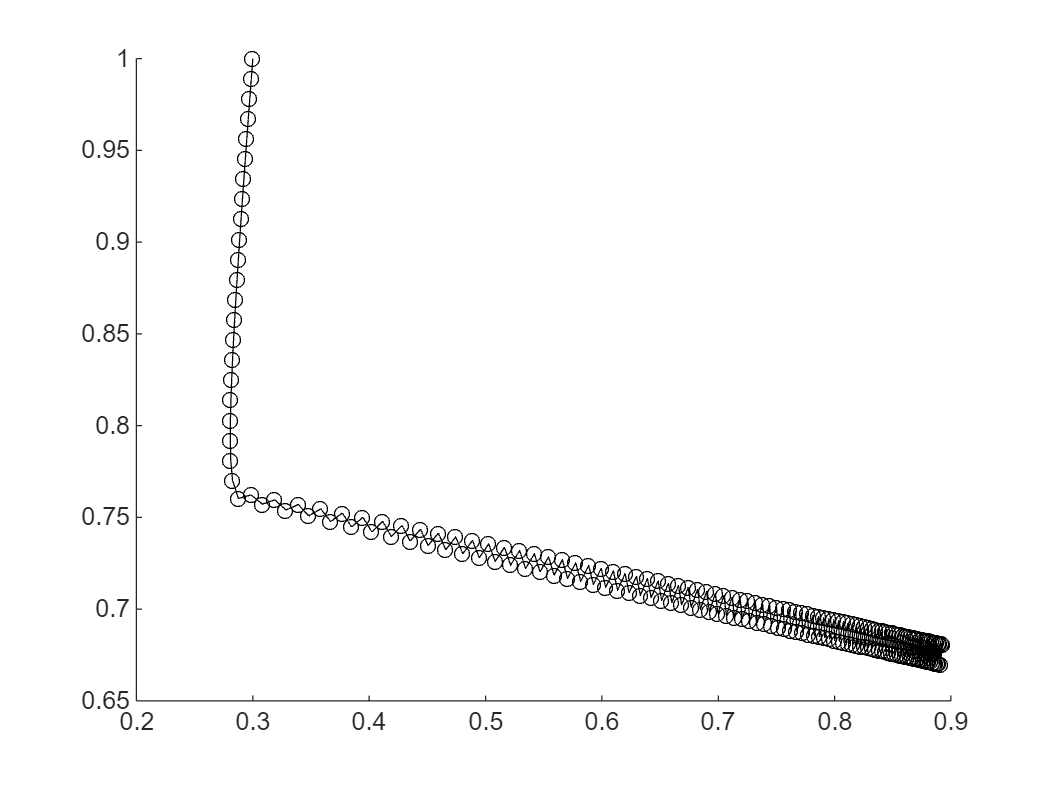

for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end

Интересно поварьировать величину шага  при помощи слайдера!

% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
ax = animated_Line.Parent;
x_lim = ax.XLim;
y_lim = ax.YLim;
Nx = 30;Ny = 30;
x_grid = linspace(x_lim(1),x_lim(2),Nx);
y_grid = linspace(y_lim(1),y_lim(2),Ny);
[X,Y] = meshgrid(x_grid,y_grid);
Z = zeros([Ny Nx]);
for iii=1:Ny
    for jjj = 1:Nx
        Z(iii,jjj) = F([x_grid(jjj) y_grid(iii)]);
    end
end
        

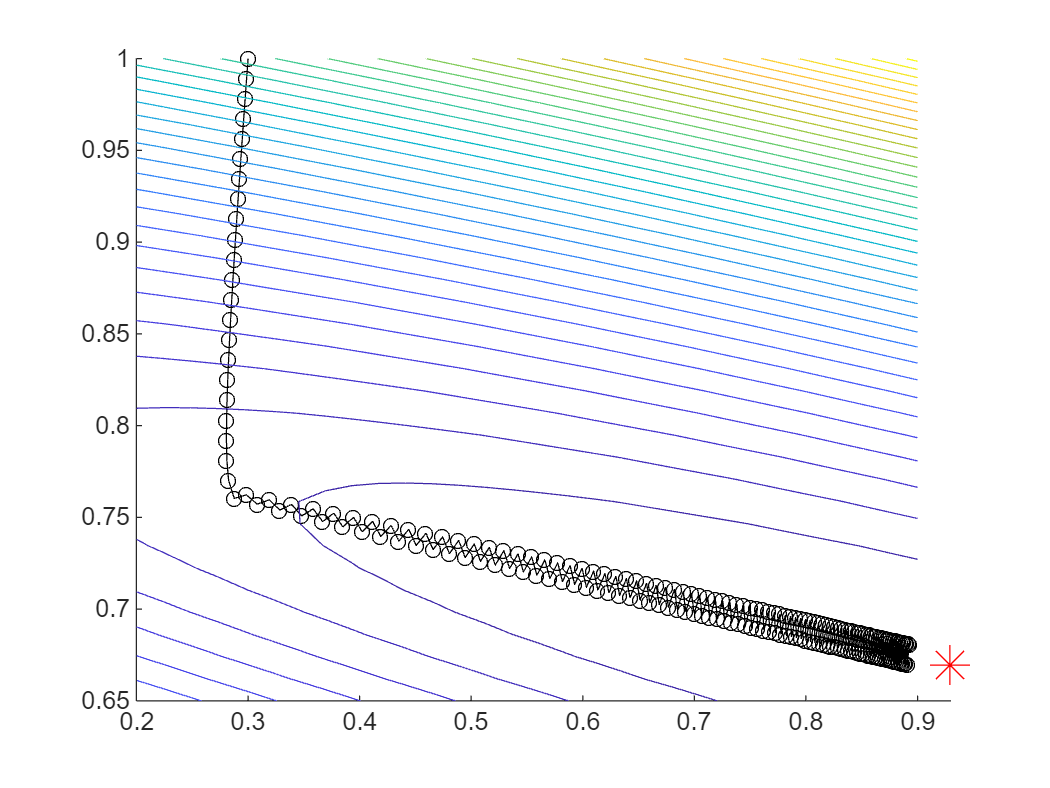

hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    contour(X,Y,Z,'LevelStep',1); % контурное изображение показывает линии постоянного значения 
hold(ax,"off");

    Для функции выбранной в качестве целевой, алгоритм на каждом шаге идет практически в одном и том же направлении, величина градиента слабо меняется от итерации к итерации

Поэтому алгоритм работы оптимизатора целесообразно модифицировать таким образом, чтобы после расчета направления градиента, совершать несколько пробных шагов в направлении противоположном градиенту без пересчета собственно градиента.   

Если происходит уменьшение значения функции на пробном шаге, то алгоритм должен развивать успех и пытаться искать оптимальное решение в том же направлении, не пересчитывая градиент заново, подобная стратегия называется линейным поиском (linesearch). Код нашего оптимизатора может быть модифицирован следующим образом:

[xval,fval,iternumber,outflag,search_history]=grad_search_linesearch([0.0 0.0],F,gradF,"mu",1,"N",100,"alfa",2, "beta",0.5, "tries",15)

xval =     0.9274
    0.6704


fval = 1.9575e-05

iternumber = 99

outflag = 1×3 logical array
   0   1   1


search_history =          0    0.2999    0.2385    0.2560    0.1353    0.1750    0.1887    0.1922    0.2950    0.2508    0.2701    0.2848    0.2900    0.2911    0.5443    0.5724    0.5669    0.5714    0.5697    0.5707    0.5743    0.5821    0.5854    0.5932    0.5962    0.5969    0.9071    0.7845    0.8280    0.8269    0.8032    0.8062    0.8123    0.8230    0.8174    0.8194    0.8474    0.8348    0.8374    0.8393    0.8431    0.8436    0.8444    0.8463    0.8471    0.8473    0.9248    0.8941    0.9049    0.9036
         0    1.9774    1.4809    1.2210    0.6115    0.6768    0.8201    0.7709    0.8619    0.7244    0.7555    0.7760    0.7450    0.7623    0.2464    0.8674    0.8048    0.7708    0.7011    0.7290    0.7132    0.7278    0.7113    0.7265    0.7094    0.7178    0.5445    0.7856    0.6785    0.7412    0.6686    0.6765    0.6855    0.6969    0.6809    0.6855    0.7089    0.6734    0.6777    0.6840    0.6771    0.6843    0.6802    0.6841    0.6798    0.6819    0.6386    0.6988  

disp("Относительняа ошибка фиттинга:" + string(norm(x_true-xval)/norm(x_true)))

Относительняа ошибка фиттинга:0.0022853



% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),Marker="o",LineStyle="-");

fig2


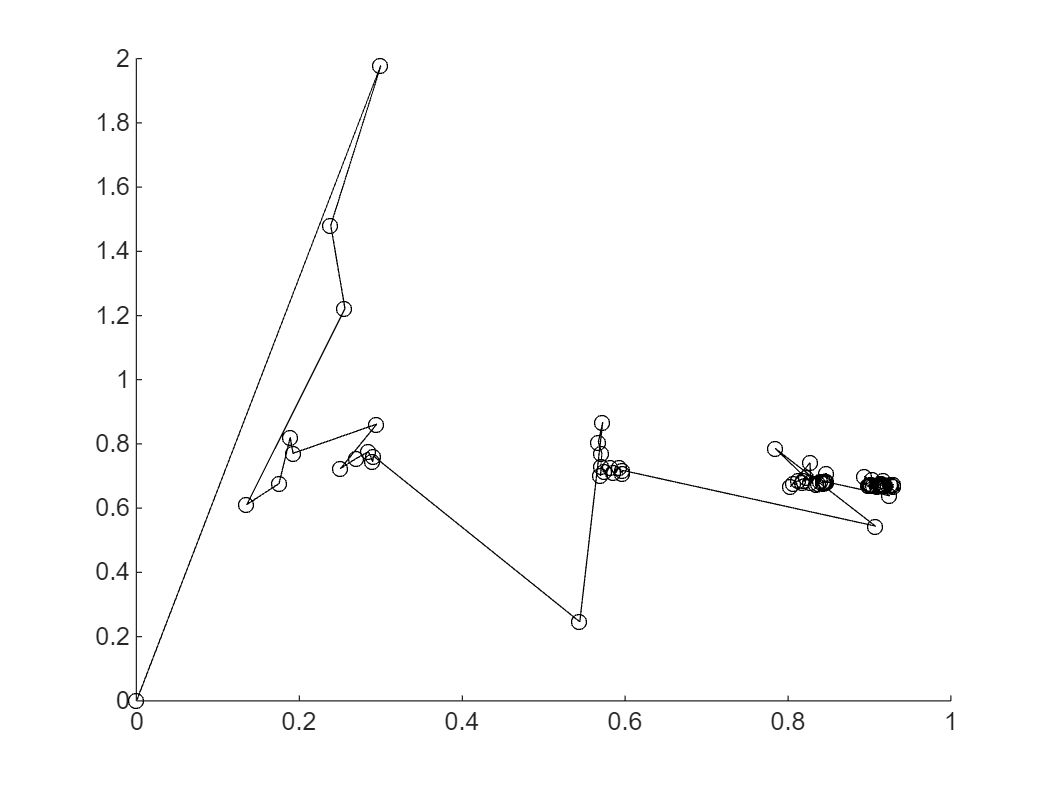

for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end

% интересно поиграться в коде с параметрами alfa и beta, которые умножают
% шаг, и уменьшают шаг, в случае неудачи

Если посмотреть на выражение для триальной функции $F(\vec{x}_{i+1}) = F(\vec{x}_{i} -\mu \hat{g}(\vec{x}_{i})) ,\ где \  \hat{g}(\vec{x}_{i})= \frac {\nabla F(\vec{x}_i)}{||\nabla F(\vec{x}_i)||}$, как на функцию от параметра $\mu
$, то фактически мы имеем оптимизационую подзадачу, найти такое $\mu$, которое давало бы минимальное значение функции:

 $argmin(F(\mu)|_{\hat{g}, \vec{x}_i})$ при фиксированных значениях $\hat{g}(\vec{x}_{i})$ и  $ \vec{x}_{i}$. Приведенный ниже код оптимизатора решает эту подзадачу путем созданной выше функции ***grad_search_linesearch_numeric.m:***

[xval,Fval,ii,flag]=grad_search_linesearch_numeric([0.5 0.5],F,gradF,"mu",0.05,"N",1000)

xval =     0.9299
    0.6700


Fval = 3.3189e-07

ii = 66

flag = 1×3 logical array
   0   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:7.6294e-05


tic;x_direct=grad_search([0.5 0.5],F,gradF,"mu",0.05,"N",100);
direct_time = toc

direct_time = 0.0027

direct_error = norm(x_true-x_direct)

direct_error = 0.0893


tic;x_linesearch=grad_search_linesearch([0.5 0.5],F,gradF,"mu",0.05,"N",100,"alfa",2, "beta",0.5, "tries",15);
line_search_time  = toc

line_search_time = 0.0049

line_search_error = norm(x_true-x_linesearch)

line_search_error = 0.0019


tic;x_linesearch_numeric=grad_search_linesearch_numeric([0.5 0.5],F,gradF,"mu",0.05,"N",100);
line_search_num_time = toc

line_search_num_time = 0.0032

linesearch_numeric_error = norm(x_true-x_linesearch_numeric)

linesearch_numeric_error = 7.6294e-05

ДАЛЬШЕ ИДЕТ БЛОК ФУНКЦИЙ

function folder = get_folder()
% функция смотрит какой файл открыт в редакторе в настоящий момент и
% возвращает путь к данному файлу
    folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function make_script(folder,name,varargin)
% функция создает текст скриптов и пишетего в файл
    arguments
        folder (1,1) string
        name (1,1) string
    end
    arguments (Repeating)
        varargin string
    end
    % формируем текст скрипта
        script1_text = string(varargin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
        if ~isfolder(folder)
            mkdir(folder)
        end
        % пишем текст скрипта в файл
        writelines(script1_text,fullfile(folder,name + ".m"));
end
function make_function(folder,name,input_args,output_args,varargin)
% функция создает текст функции и пишет его в файл
    arguments
        folder (1,1) string
        name (1,1) string
        input_args string
        output_args string
    end
    arguments (Repeating)
        varargin string
    end
    argin = cell(1,2+ numel(varargin));
    head = "function ";
    if ~isempty(output_args)
        head = head + "[" + join(output_args,",") + "] = ";
    end
    head =head + name;
    if isempty(input_args)
        head = head +"()";
    else
        head = head +"(" + join(input_args,",")+")";
    end
    argin{1} = head;
    argin(2:end-1) = varargin;
    argin{end} = "end";
    % формируем текст скрипта
    fun_text = string(argin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
    if ~isfolder(folder)
        mkdir(folder)
    end
    % пишем текст скрипта в файл
    writelines(fun_text,fullfile(folder,name + ".m"));
end
function code = read_code(fun_name)
    switch class(fun_name)
        case "string"
            filename = functions(str2func(fun_name)).file;
        case "function_handle"
            filename = functions(fun_name).file;
        otherwise
            code = '';
            return
    end
    if isempty(filename)
        code = fun_name;
        return 
    end
    code = string(fileread(filename));
end
function varargout = vararargout_function(varargin)
    % varargout  - тоже особое слово, в теле функции оно означает, что
    % данный массив ячеек возвращается как splat - функции
    disp(['Число входных аргументов: ' num2str(nargin)]);
    disp(['Число вЫходных аргументов: ' num2str(nargout)]);
    
    number_output_arguments = nargout; % особое слово, чтобы узнать число выходных аргументов, находясь фнутри функции
    varargout = cell(1,number_output_arguments);
    for counter=1:numel(varargin)
        if counter>number_output_arguments
            return
        else
            varargout{counter}=svds(varargin{counter});
        end
    end       
end
function out = ignore_arguments(x,~,~)
    out = sin(x);
end
function no_ignore_arguments(x,y,z) % аргументы фигурируют, но не игнорируются
    out = sin(x);
end
function [A,B] = call_handle(A,B,fun_handle)
    [A,B] = fun_handle(A,B);
end
function [A,B,nested_fun_handle] = external_fun(A,B)
     who
    nested_fun() % вызов вложенной функции (может быть в любом месте, вложенная функция - не скрипт!
    function nested_fun() % объявление вложенной функции
        disp("workspace вложенной функции")
        who % почему не работает второй ху?
        [A,B] = swap(A,B); % переменные во внешней функции для вложенной функции являются глобальными
    end
    nested_fun_handle = @nested_fun;
end
function [A,B] =multi_embedded_fun(A,B)
    embedded_fun()
    function embedded_fun()
        embedded_fun()
        function embedded_fun()
            embedded_fun()
            function embedded_fun()
                embedded_fun()
                function embedded_fun()
                    embedded_fun()
                    function embedded_fun()
                        embedded_fun()
                        function embedded_fun()
                            who
                            [A,B] = swap(A,B);
                        end 
                    end 
                end 
            end 
        end 
    end 
end
function out = annotated_arguments(A,B,C)
    arguments 
        A (1,1) {mustBeInteger,mustBePositive} % означает, что аргументы должен быть целым
        B (1,:) double % дополнительно указан тип аргумента, также размерность указана частично!
        C (1,1) string {mustBeMember(C,["sin" "cos" "tan"])} ="sin" % 
    end
    out = repmat(transpose(B),[1 A]);
    fun_handle = str2func(C);
    for i = 2:A
        out(:,i) = fun_handle(out(:,i-1));
    end
end
% function out = name_value_pairs(options)
% % Важно при написании функций делать к ним хорошую документацию. 
% % Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% % структуре и области определения входных аргументов функции многое говорит о функции
%     arguments 
%         options.A (1,1) {mustBeInteger,mustBePositive} = 3 % означает, что аргументы должен быть целым
%         options.B (1,:) double = linspace(-pi,pi,100) % дополнительно указан тип аргумента, также размерность указана частично!
%         options.C (1,1) string {mustBeMember(options.C,["sin" "cos" "tan"])} ="sin" % 
%     end
%     out = repmat(transpose(options.B),[1 options.A]);
%     fun_handle = str2func(options.C);
%     for i = 1:A
%         out = fun_handle(out);
%     end
% end
function C = input_expression(expression)
    C = eval(expression);
    whos
    caller_killer()
    whos 
end
function caller_killer()
    evalin('caller','clearvars');
end

function C = assign_in_function(expression)
    C = eval(expression);
    whos
    assignin_internal_fun()
    whos 
end
function assignin_internal_fun()
    evalin('caller','C=pi');
end
function [y,p] = persistent_func(f,dx)
% функция сдвигает фазу аргумента функции f на величину dx
    persistent x
    persistent animated_Line axes_handle; % при первом пуске persistent переменная []
    if isempty(x)
        x =-dx; % обнуляем сдвиг в начальный момент
    end
    if isempty(animated_Line)
        axes_handle = axes(figure(10),"XTickMode","manual","YTickMode","manual","XLim",[0,2*pi],"YLim",[-1 1]);
        animated_Line = animatedline(axes_handle,"Marker","o","LineStyle","none");
    end
    x=x+dx;
    y = f(x);
    addpoints(animated_Line,x,y);
    drawnow  
end
function out = repeating_name_value_pairs(name,value)
% Важно при написании функций делать к ним хорошую документацию. 
% Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% структуре и области определения входных аргументов функции многое говорит о функции
    arguments (Repeating)
        name (1,1) string  % означает, что аргументы должен быть целым
        value (1,:) double  % дополнительно указан тип аргумента, также размерность указана частично!
    end
    out = cellstr(name) + "=" + string(cell2mat(value));
end
function out = exist_check_fun(A,B,C)
% функция exist(variable_name,"var") проверяет существует ли переменная с именем variable_name
out = 0;
    if exist('A','var')
            out = out + A;
    end
    if exist('B','var')
            out = out + B;
    end
    if exist('C','var')
            out = out + C;
    end
end
function on_clean_up_check(expr,f_handle)
    on_clean_up_obj = onCleanup(f_handle);
    eval(expr);
    pause(5)
    
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end